% Definiranje koordinat baznih postaj
bazne_postaje = [1, 1; 10, 5; 2, 4];  % pozicije treh stolpov

% Pridobivanje meritev razdalj do posameznih stolpov
meritve = [ping_stolp_1(), ping_stolp_2(), ping_stolp_3()];

% Inicializacija začetne ocene
zacetna_ocena = [5, 5];

% Klicanje Levenberg-Marquardt metode
[koncni_parametri, zgodovina] = levenberg_marquardt(@model, zacetna_ocena, bazne_postaje, meritve, 100, 1e-6);
fprintf('Končne koordinate telefona: (%f, %f)\n', koncni_parametri(1), koncni_parametri(2));

Končne koordinate telefona: (5.249076, 2.095850)


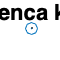


% afna predstavlja kazalec, lahko posredujemo funckijo kot argument drugi
% funckiji

% Prikaz konvergence koordinat
plot(zgodovina(:,1), zgodovina(:,2), '-o');
xlabel('X koordinata');
ylabel('Y koordinata');
title('Konvergenca koordinat');


% Modelna funkcija

function razlike = model(parametri, bazne_postaje, meritve)
% funckija računa razlike med izmerjenimi razdaljami do baznih postaj in
% izračunane razdalje glede na trenutno oceno telefona
    x = parametri(1);   % trenutna ocena koordinat [x, y]
    y = parametri(2);
    razlike = zeros(size(bazne_postaje, 1), 1); 
    % razlike so na začetku vse enake 0, velikost vektorja je enaka številu
    % baznih postaj
    for i = 1:length(razlike)
        razdalja = sqrt((x - bazne_postaje(i, 1))^2 + (y - bazne_postaje(i, 2))^2);
        razlike(i) = razdalja - meritve(i);
    end
    % iteriramo skozi vsako bazno postajo. Evklidska razdalja od trenutne
    % ocene pozicije telefona do posamezne bazne postaje. Vektor razlike je
    % velik 3 elemente
end

% Levenberg-Marquardt metoda
function [parametri, zgodovina] = levenberg_marquardt(model, parametri, bazne_postaje, meritve, max_iter, tol)
% parametri - ocenjene koordinate telefona
% zgodovina - matrika z vsebino vseh iteracij parametrov
% ------------------------------------------------------
% model - funkcija, ki računa razdaljo med izmerjenimi in izračunanimi
% razdaljami
% parametri - začetna ocena koordinat telefona
% bazne postaje- matrika koordinat baznih postaj
% meritve - vektor izmerjenih razdalj do baznih postaj
% max iter-max število iteracij
% tol-toleranca za konvergenco, da se ustavi
    lambda = 0.01;  %damping parametra za stabilnost
    zgodovina = []; %matrika za hranjenje iteracij parametrov
    for iter = 1:max_iter
        razlike = model(parametri, bazne_postaje, meritve); % računamo razdaljo med izmerjenimi in izračunami razdaljami
        J = jacobian(@(p) model(p, bazne_postaje, meritve), parametri); % Dobimo jakobijevo matriko
        H = J' * J + lambda * eye(length(parametri));   % dobimo hessejevo matriko in dodamo damping
        g = J' * razlike;   % gradient zračunamo kot J' * razlike
        delta = -H \ g;     % za koliko spremenimo parametre, korak optimizacije, delimo Hessejevo matriko z gradientom
        parametri = parametri + delta';     % posodobimo parametre
        zgodovina = [zgodovina; parametri];     % posodobimo zgodovino z zadnjo iteracijo
        if norm(delta) < tol        % preverimo, ali je popravek manjši od tolerance za zaključek optimizacije
            break;
        end
    end
end

% Izračun Jakobijeve matrike
function J = jacobian(fun, parametri)
%računamo približke parcialnih odvodov
%parametri_eps-parametriz majhnim dodatkom za numerično diferenciranje
    eps = 1e-6;     %nekaj malega, za odvode
    f0 = fun(parametri);        %funkcija trenutno
    n = length(parametri);
    m = length(f0);
    J = zeros(m, n);
    for i = 1:n
        parametri_eps = parametri;
        parametri_eps(i) = parametri(i) + eps;
        fi = fun(parametri_eps);    %funckija po premiku
        J(:, i) = (fi - f0) / eps;
    end
end
